# April Tag Detection Example

*Ben Morris, 4/12/22, Revision A*

This live script will walk through April Tag detection with MATLAB

## Setup

First step is to create the camera. For laptops with integrated webcams, the external cam will be `webcam(2)`.

clear cam
cam = webcam(1);

We can take an image from the camera like this:

img = snapshot(cam);
% If this gives a Time Out error, restart MATLAB
% If the image is all black, remove the camera lens
% If the image is still all black, rotate the C<-->O slider on the camera
% all the way to O.
% If the image is still black, restart MATLAB.

And display it on custom figure:

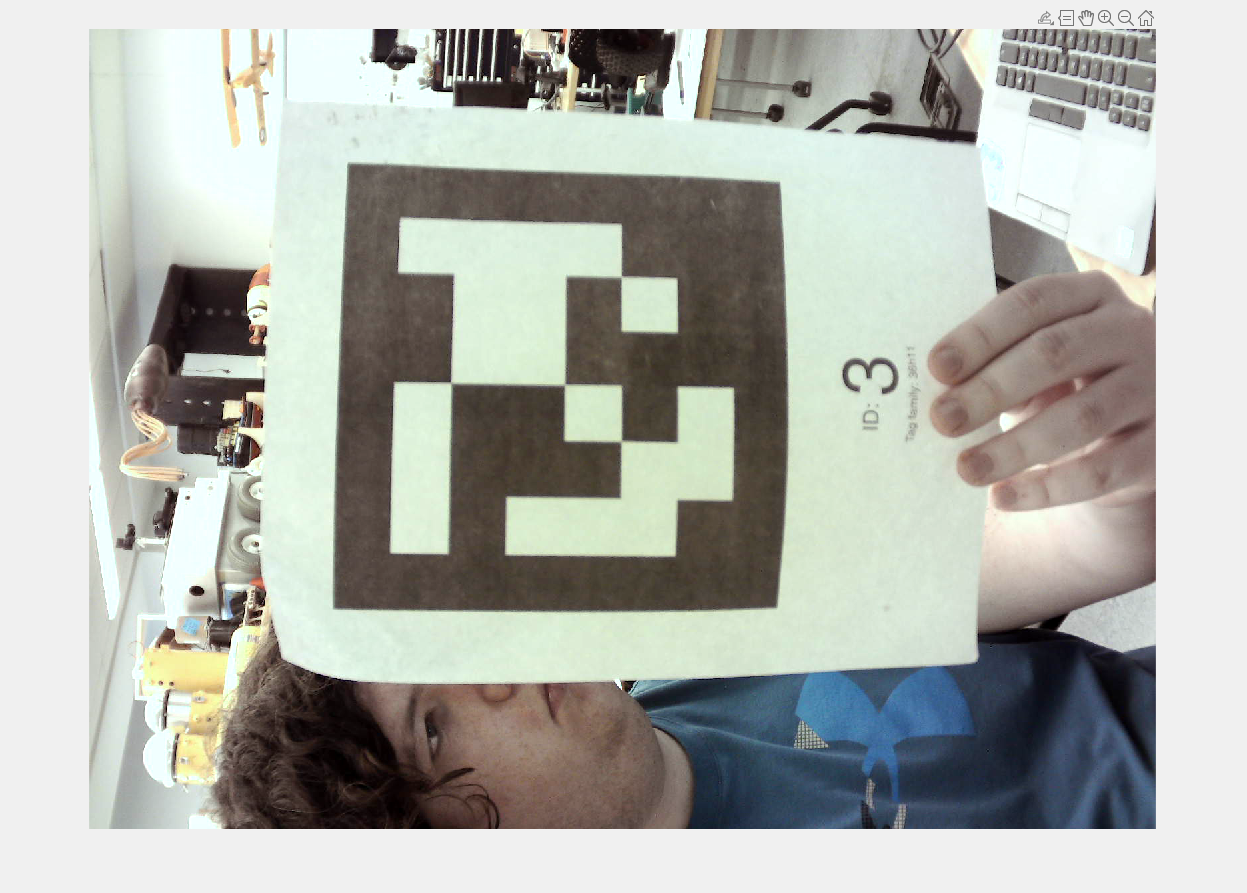

tagFig = figure('Name','April Tag Detection', 'NumberTitle','off', 'Visible','on');
imshow(img);

Load the camera intrinsics so MATLAB can translate april tag detection to 3-D Pose

load ../cameraParams.mat
intrinsics = cameraParams.Intrinsics;

Other variables - tag size (mm), how big the axes should be, and the world points

tagSize = 164;
axisLength = tagSize * 2 / 3;
axesPoints = [0 0 0; axisLength 0 0; 0 axisLength 0; 0 0 axisLength];

`axesPoints` contains 4 points in April Tag coordinates

- Center of april tag (origin for the axes)

- End of X-Axis

- End of Y-Axis

- End of Z-Axis

## Detect April Tag

MATLAB has april tag detection. You need to give it the image, the tag family (in most cases, `tag36h11`), the camera intrinsics, and the size of the tag in mm*.

`readAprilTag` does not need to take in the intrinsics or tag size, but if it does not it will not give the pose of the tag (only the id and the corners)

[id, corners, pose] = readAprilTag(img, 'tag36h11', intrinsics, tagSize);

**does not really need to be mm - the units of the output will be in the same units as this. mm used for consistency.*

`id` is the ID of the tag that is seen

id

id = 4

`corners` gives the coordinates of the corners of the tag. These can be plotted on the original figure:

corners

corners = 1.0e+03 *

    1.0056    0.8971
    1.0179    0.3091
    0.4392    0.3079
    0.4279    0.8841


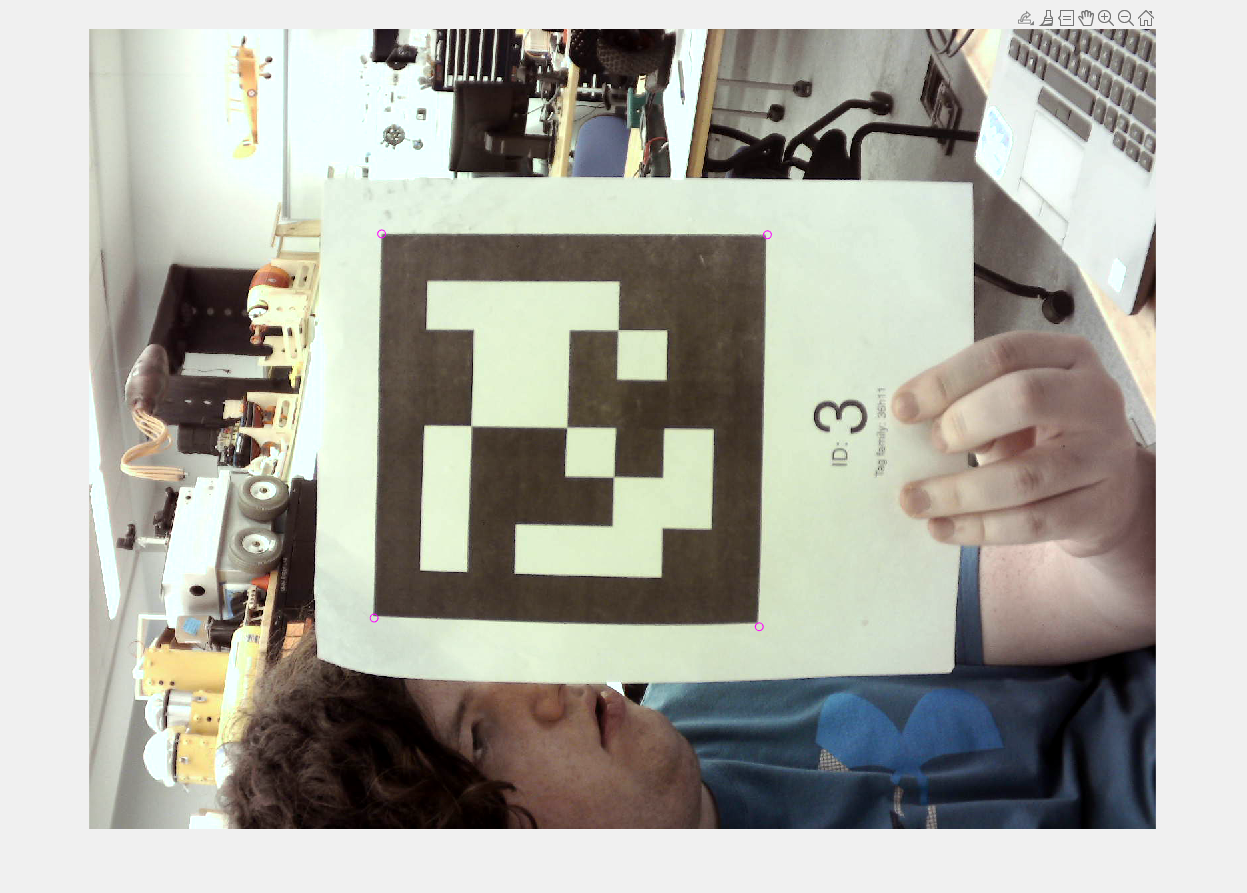


figure(tagFig);
hold on;
plot(corners(:, 1), corners(:, 2), 'om');

Finally, `pose` gives the pose of the april tag relative to the camera.

pose

pose =   rigid3d with properties:

       Rotation: [3×3 double]
    Translation: [-64.8116 -48.0635 1.7071e+03]


rot = pose.Rotation

rot =     0.0182   -0.9995    0.0268
    0.9963    0.0159   -0.0849
    0.0844    0.0283    0.9960


trans = pose.Translation

trans = 1.0e+03 *

   -0.0648   -0.0481    1.7071


## Plot Axes

A helpful visualization for April Tags is to plot the three axes in different colors. This shows the center of the tag along with the orientation. By convention, red is the X axis (pointing to the right of the tag), green is the Y axis (pointing down, not up for some reason), and blue is the Z axis (pointing out of the tag).

The four points needed are defined in `axesPoints`:

axesPoints

axesPoints =          0         0         0
  109.3333         0         0
         0  109.3333         0
         0         0  109.3333


MATLAB's `worldToImage` function takes in the camera intrinsics, the pose of the origin, and a set of coordinates in the POV of the pose, and returns the corresponding pixel coordinates.

imagePoints = worldToImage(intrinsics, pose.Rotation, pose.Translation, axesPoints);
imagePoints

imagePoints = 1.0e+03 *

    0.7204    0.5982
    0.7278    0.2061
    1.1036    0.6035
    0.7645    0.6190


We can draw these axes with a few plots:

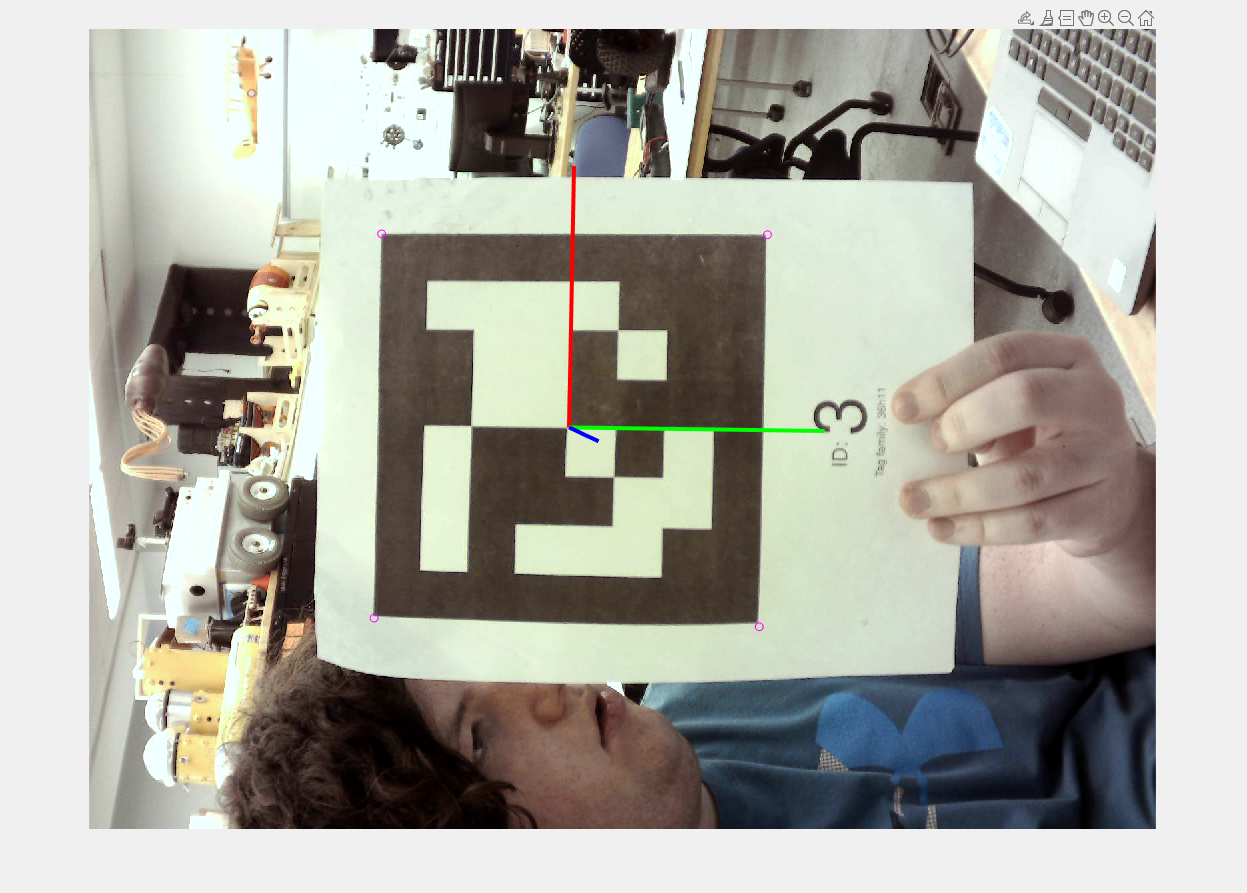

figure(tagFig);
hold on
colors = ['-r'; '-g'; '-b'];
for i = 1:3
    pixels = [imagePoints(1, :); imagePoints(i+1, :)];
    plot(pixels(:, 1), pixels(:, 2), colors(i, :), 'LineWidth', 3);
end
hold off

## Run in Loop

Let's put it all together

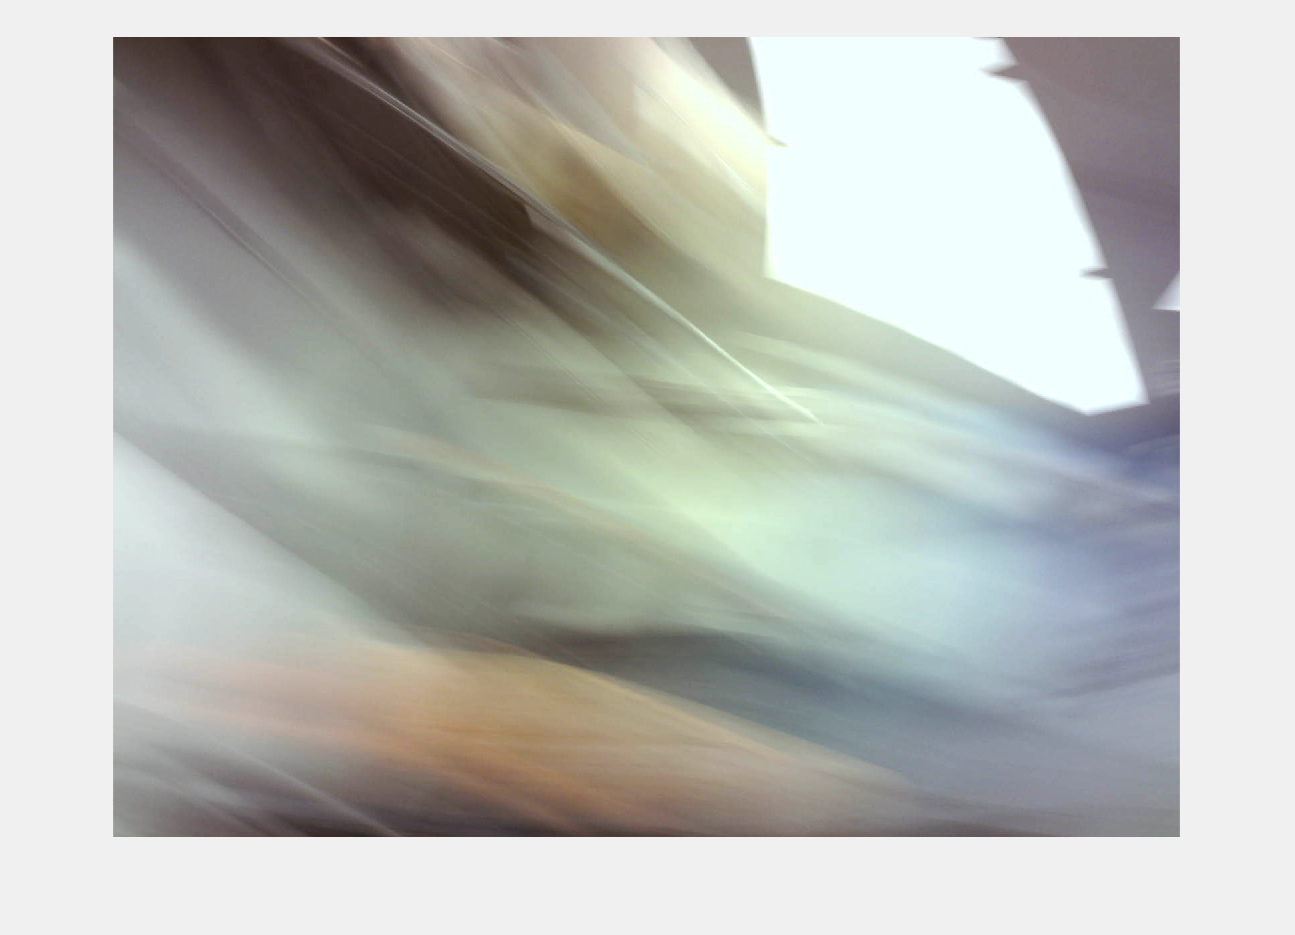

while true
    % Check if figure still exists
    try
        figure(tagFig);
    catch
        break
    end

    % Get snapshot
    clear cam
    cam = webcam(2);
    img = snapshot(cam);

    % Plot image
    clf;
    imshow(img);
    hold on;

    % Detect tags
    [id, corners, pose] = readAprilTag(img, 'tag36h11', intrinsics, tagSize);
    if isempty(id)
        continue
    end
    
    % Plot the corners of the tag
    plot(corners(:, 1), corners(:, 2), 'om');
    
    % Get image coordinates for axes.
    imagePoints = worldToImage(intrinsics, pose.Rotation, pose.Translation, axesPoints);
    
    % Draw colored axes.
    for i = 1:3
        pixels = [imagePoints(1, :); imagePoints(i+1, :)];
        plot(pixels(:, 1), pixels(:, 2), colors(i, :), 'LineWidth', 3);
    end
    
    hold off;
end

## Shutdown

clear cam